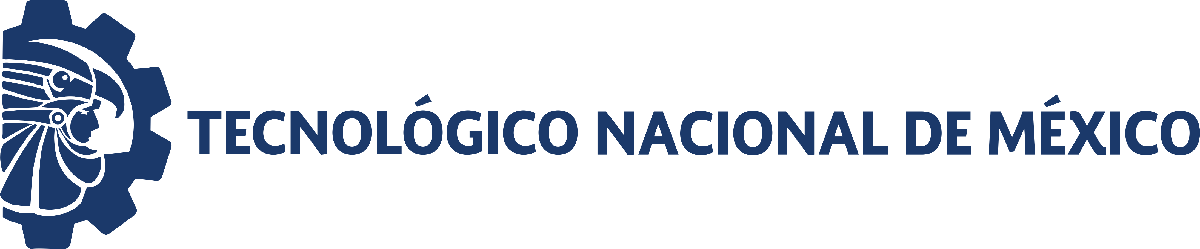                                 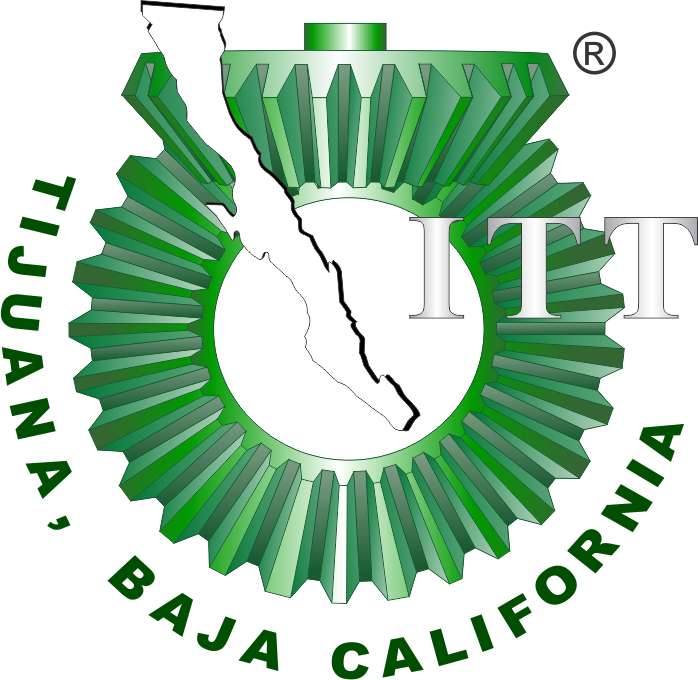

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

# Proyecto: Correlación en el tamaño poblacional de células sanas y células cancerígenas con respecto a sus tasas de absorción de nutrientes.

## Información general

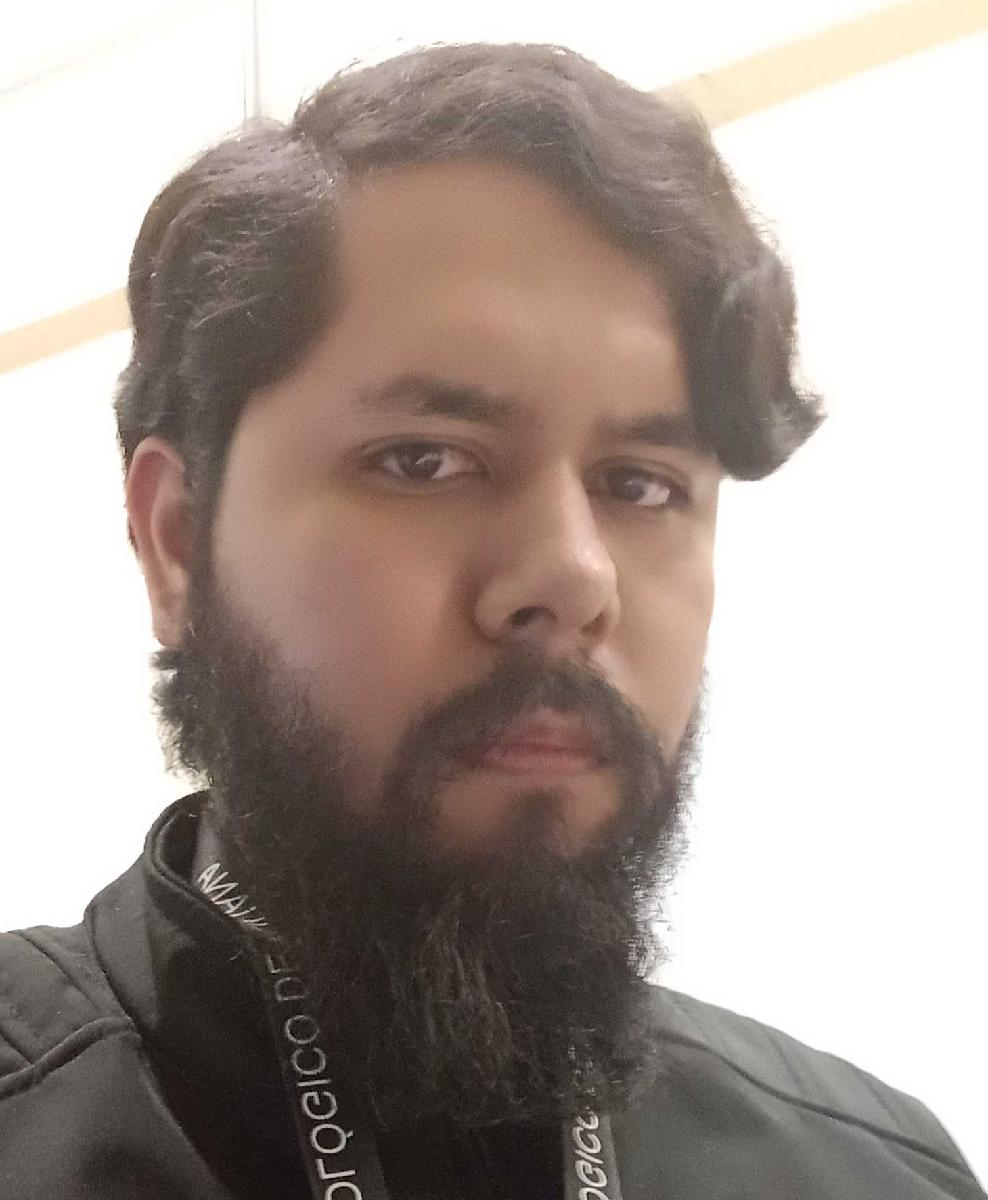

Nombre del alumno: **Vincent Alejandro Villela Salinas**

Número de control: **M25210045**

Correo institucional: **M25210045@tectijuana.edu.mx**

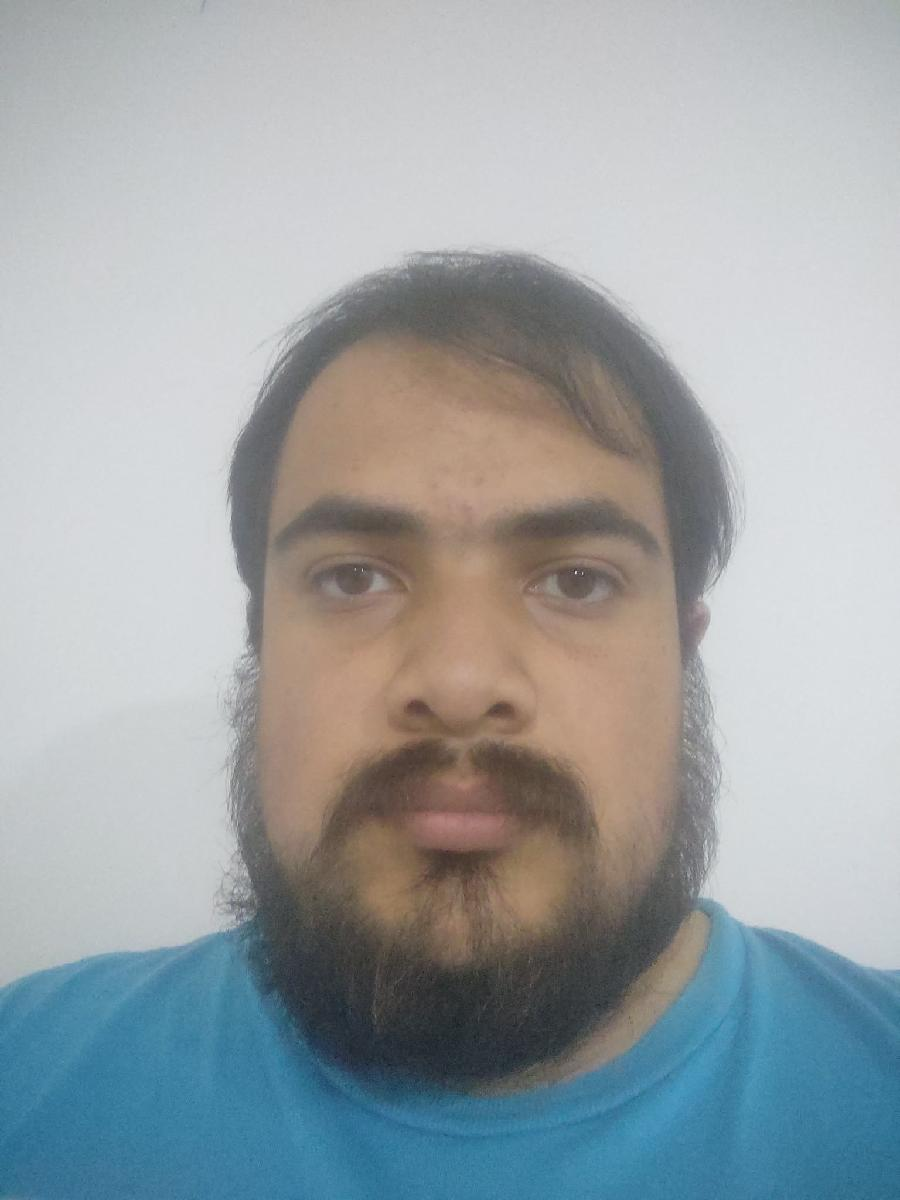

Nombre del alumno: **Oscar González  Ramírez**

Número de control: **M25210050**

Correo institucional: **M25210050@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## **Objetivo**

Estructurar un modelo matemático a partir de un conjunto selecto de datos experimentales utilizando teorías de sistemas dinámicos no lineales y técnicas de regresión lineal. Dichos datos provienen de uno de 3 conjuntos de variables biológicas registradas en la siguiente tabla:

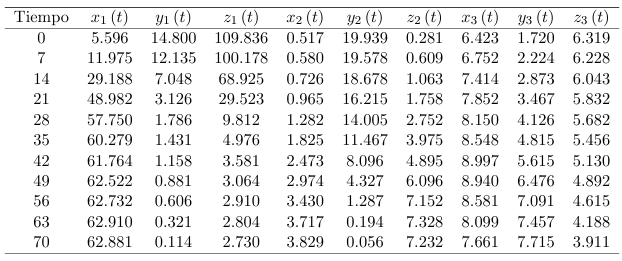

Tabla. Los datos experimentales in vitro correspondientes a la interacción entre tres variables biológicas y su evolución en el tiempo medido en días.

Tomando como datos referenciales el conjunto de datos `x2(t), y2(t), z2(t)` se forma un sistema de 3 EDOs con la siguiente estructura a evaluar:


$$\dot{x} =\rho_1 x+\rho_2 \textrm{xyz}-\rho_3 x^3 -\rho_4 {\textrm{yx}}^2$$



$$\dot{y} =\rho_5 y+\rho_6 {\textrm{zy}}^2 +\rho_7 y^2 z^2 -\rho_8 \textrm{yz}$$



$$\dot{z} =\rho_9 z+\rho_{10} z^3 -\rho_{11} z^2 -\rho_{12} {\textrm{xz}}^3$$


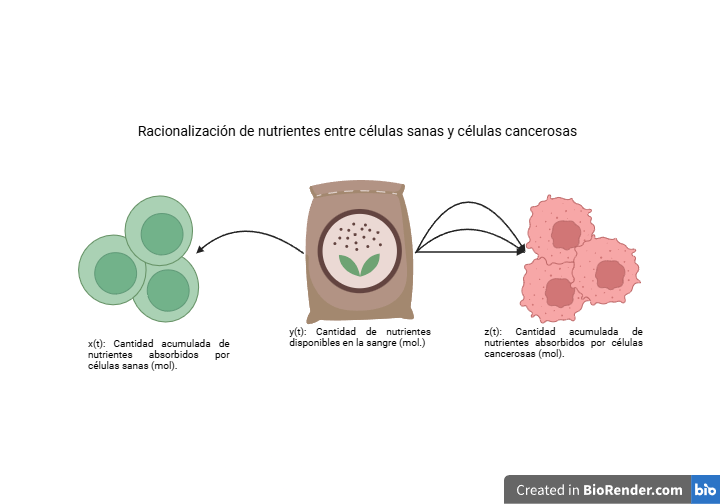

Figura. Representación gráfica del sistema biológico hecho con [https://bioart.niaid.nih.gov/](https://bioart.niaid.nih.gov/) o [https://www.biorender.com/](https://www.biorender.com/).

## Referencias

[1] Valle, Paul A., Syllabus para Biología de Sistemas y Gemelos Digitales, Tecnológico Nacional de México / Instituto Tecnológico de Tijuana, Tijuana, B.C., México, 2026. Permalink: [https://biomath.xyz/course/](https://biomath.xyz/course/) 

## Datos experimentales, suavizados y normalizados

clc; clear; close all; warning('off','all')
smooth = true; normalize = true;
[t, d1, d2, d3] = getdata('data.csv',smooth,normalize);
plotdata(t, d1, d2, d3); exportgraphics(gcf, 'data_smooth_normal.pdf','ContentType','vector')

## Modelado matemático y ajuste de datos

x = d2(:,1); y = d2(:,2); z = d2(:,3);
rho = [0.0466 0.00202 0.00281 0.00384 0.00576 0.000322 0.000322 0.0289 0.115 0.00685 0.0378 0.00104];
mdl = Variant(t,x,y,z,rho);
fa = mdl.Fitted;
fa = reshape(fa,[],3);
xa = fa(:,1); ya = fa(:,2); za = fa(:,3); ta = t;
plotresults(t,x,y,z,ta,xa,ya,za); ...
    exportgraphics(gcf,'data_fitted.pdf','ContentType','vector')

## Predicción del comportamiento a 2t

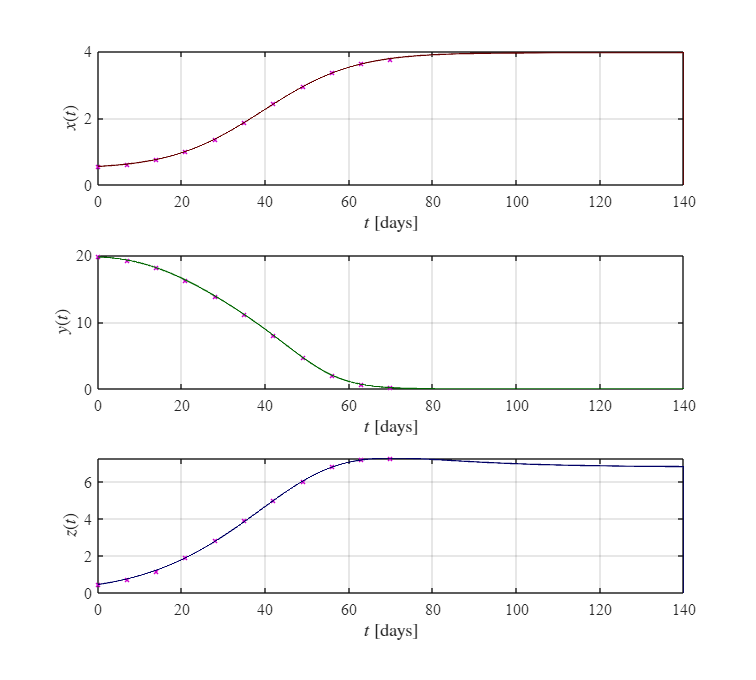

%Se usan los valores estimados
clear; close all
smooth = true; normalize = true;
[t, ~, d2, ~] = getdata('data.csv',smooth,normalize);
x = d2(:,1); y = d2(:,2); z = d2(:,3);
rho = [0.059217 0.0031917 0.0038018 0.0068103 0.0073627 0.00023069 0.00026903 0.025808 0.083189 0.0023378 0.0167 0.00042632];
tend = t(end); dt = 1E-3;
control = 'nada';
[th,xh,yh,zh] = sysheun(x,y,z,rho,2*tend,dt,control);
plotresults(t,x,y,z,th,xh,yh,zh); exportgraphics(gcf, 'modelo_heun.pdf','ContentType','vector')

## Puntos de equilibrio

clc; clear
syms x y z rho1 rho2 rho3 rho4 rho5 rho6 rho7 rho8 rho9 rho10 rho11 rho12
dx_dt = rho1*x + rho2*x*y*z - rho3*x^3 - rho4*y*x^2;
dy_dt = rho5*y + rho6*z*y^2 + rho7*(y^2)*(z^2) - rho8*y*z;
dz_dt = rho9*z + rho10*z^3 - rho11*z^2 - rho12*x*z^3;
fxyz = solve([dx_dt,dy_dt,dz_dt],[x y z]);
fprintf(['Puntos de equilibrio del sistema: ',num2str(length(fxyz.x))]);
xe_1 = fxyz.x(1); ye_1 = fxyz.y(1); ze_1 = fxyz.z(1);
xe_2 = fxyz.x(2); ye_2 = fxyz.y(2); ze_2 = fxyz.z(2);
xe_3 = fxyz.x(3); ye_3 = fxyz.y(3); ze_3 = fxyz.z(3);
fprintf('Puntos de equilibrio simbólicos: '); disp([xe_1,ye_1,ze_1;xe_2,ye_2,ze_2;xe_3,ye_3,ze_3])
for i = 12
    disp([fxyz.x(i);fxyz.y(i);fxyz.z(i)])
end

### Matriz jacobiana

J = jacobian([dx_dt, dy_dt, dz_dt],[x, y, z]);
fprintf('Matriz Jacobiana: \n'); disp(J)

## Estabilidad local

clc; clear; close all; warning('off','all')
par = [0.0466 0.00202 0.00281 0.00384 0.00576 0.000322 0.000322 0.0289 0.115 0.00685 0.0378 0.00104];
E = equilibria(par);

## Simulink

clear; close all
smooth = true; normalize = true;
[t, ~, d2, ~] = getdata('data.csv',smooth,normalize);
x = d2(:,1); y = d2(:,2); z = d2(:,3);
rho = [0.059217 0.0031917 0.0038018 0.0068103 0.0073627 0.00023069 0.00026903 0.025808 0.083189 0.0023378 0.0167 0.00042632];
mdl = Variant(t,x,y,z,rho);
file = 'Proyecto_simulink';
sim(file);
parameters.StopTime = '70';

## Variable de control: Rampa unitaria

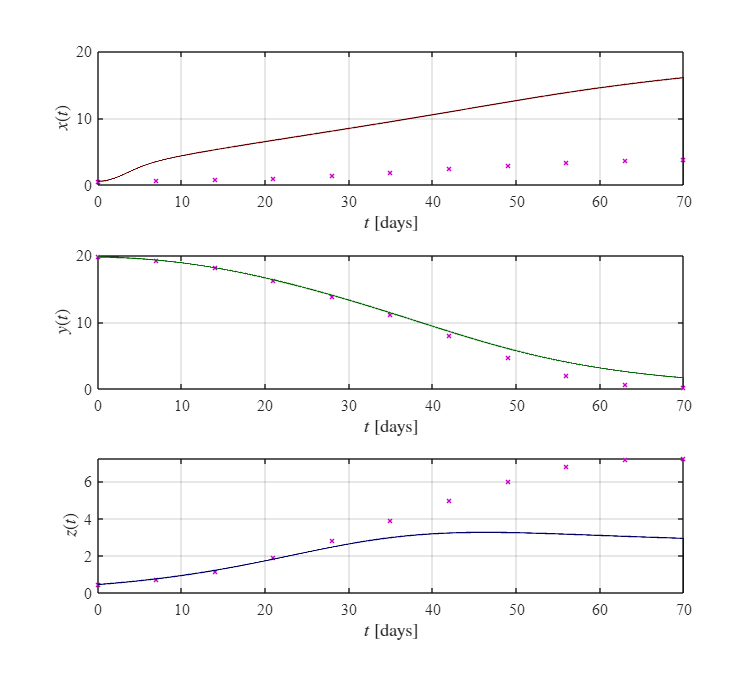

clear; close all
smooth = true;
normalize = true;
[t, ~, d2, ~] = getdata('data.csv',smooth,normalize);
x = d2(:,1); y = d2(:,2); z = d2(:,3);
rho = [0.059217 0.0031917 0.0038018 0.0068103 0.0073627 0.00023069 0.00026903 0.025808 0.083189 0.0023378 0.0167 0.00042632];
tend = t(end);
dt = 1E-3;
control = 'rampa';
[th,xh,yh,zh] = sysheun(x,y,z,rho,tend,dt,control);
plotresults(t,x,y,z,th,xh,yh,zh); exportgraphics(gcf,'variable_control.pdf','ContentType','vector')

## Funciones

### Datos experimentales

function [t,d1,d2,d3,par] = getdata(file,smooth,normalize)
    sys = readmatrix(file);
    t = round(sys(:,1));
    d1 = [sys(:,2),sys(:,3),sys(:,4)];
    d2 = [sys(:,5),sys(:,6),sys(:,7)];
    d3 = [sys(:,8),sys(:,9),sys(:,10)];

    alpha1 = 0.118; beta1 = 0.0448; delta1 = 0.0266;
    alpha2 = 0.0235; beta2 = 0.131; delta2 = 0.264;
    alpha3 = 0.0117; beta3 = 0.0825; delta3 = 0.0443;
    par = [alpha1,beta1,delta1,alpha2,beta2,delta2,alpha3,beta3,delta3];

    if smooth == false && normalize == false
    return
    elseif smooth == true && normalize == false
        for i = 1:3
        d1(:,i) = smoothdata(d1(:,i),'gaussian',5);
        d2(:,i) = smoothdata(d2(:,i),'gaussian',5);
        d3(:,i) = smoothdata(d3(:,i),'gaussian',5);
        end
    elseif smooth == false && normalize == true
        t = t - t(1);
        for i = 1:3
        d1(:,i) = d1(:,i)/max(d1(:,i));
        d2(:,i) = d2(:,i)/max(d1(:,i));
        d3(:,i) = d3(:,i)/max(d1(:,i));
        end
    elseif smooth == true && normalize == true
        t = t - t(1);
        for i = 1:3
        d1(:,i) = smoothdata(d1(:,i),'gaussian',5);
        d2(:,i) = smoothdata(d2(:,i),'gaussian',5);
        d3(:,i) = smoothdata(d3(:,i),'gaussian',5);
        d1(:,i) = d1(:,i)/max(d1(:,i));
        d2(:,i) = d2(:,i)/max(d1(:,i));
        d3(:,i) = d3(:,i)/max(d1(:,i));
        end
    end
end

function plotdata(t, d1, d2, d3)
    set(figure(), 'color', 'w')
    set(gcf, 'units', 'centimeters', 'position', [1 1 25 25])
    FS = 10;

    subplot(3, 3, 1); box on; hold on;
    plot(t, d1(:,1), '-', 'LineWidth', 1,'Color', [0.85 0.325 0.098])
    xlabel('$t (dias)$','Interpreter','latex','FontSize',FS)
    ylabel('$x_1(t)$','Interpreter','latex','FontSize',FS)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)

    subplot(3, 3, 2); box on; hold on;
    plot(t, d1(:,2), '-', 'LineWidth', 1,'Color', [0.85 0.325 0.098])
    xlabel('$t (dias)$','Interpreter','latex','FontSize',FS)
    ylabel('$y_1(t)$','Interpreter','latex','FontSize',FS)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)

    subplot(3, 3, 3); box on; hold on;
    plot(t, d1(:,3), '-', 'LineWidth', 1,'Color', [0.85 0.325 0.098])
    xlabel('$t (dias)$','Interpreter','latex','FontSize',FS)
    ylabel('$z_1(t)$','Interpreter','latex','FontSize',FS)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)

    subplot(3, 3, 4); box on; hold on;
    plot(t, d2(:,1), '-', 'LineWidth', 1,'Color', [0.85 0.325 0.098])
    xlabel('$t (dias)$','Interpreter','latex','FontSize',FS)
    ylabel('$x_2(t)$','Interpreter','latex','FontSize',FS)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)

    subplot(3, 3, 5); box on; hold on;
    plot(t, d2(:,2), '-', 'LineWidth', 1,'Color', [0.85 0.325 0.098])
    xlabel('$t (dias)$','Interpreter','latex','FontSize',FS)
    ylabel('$y_2(t)$','Interpreter','latex','FontSize',FS)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)

    subplot(3, 3, 6); box on; hold on;
    plot(t, d2(:,3), '-', 'LineWidth', 1,'Color', [0.85 0.325 0.098])
    xlabel('$t (dias)$','Interpreter','latex','FontSize',FS)
    ylabel('$z_2(t)$','Interpreter','latex','FontSize',FS)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)

    subplot(3, 3, 7); box on; hold on;
    plot(t, d3(:,1), '-', 'LineWidth', 1,'Color', [0.85 0.325 0.098])
    xlabel('$t (dias)$','Interpreter','latex','FontSize',FS)
    ylabel('$x_3(t)$','Interpreter','latex','FontSize',FS)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)

    subplot(3, 3, 8); box on; hold on;
    plot(t, d3(:,2), '-', 'LineWidth', 1,'Color', [0.85 0.325 0.098])
    xlabel('$t (dias)$','Interpreter','latex','FontSize',FS)
    ylabel('$y_3(t)$','Interpreter','latex','FontSize',FS)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)

    subplot(3, 3, 9); box on; hold on;
    plot(t, d3(:,3), '-', 'LineWidth', 1,'Color', [0.85 0.325 0.098])
    xlabel('$t (dias)$','Interpreter','latex','FontSize',FS)
    ylabel('$z_3(t)$','Interpreter','latex','FontSize',FS)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
end

function plotresults(t,x,y,z,th,xh,yh,zh)
    set(figure(),'Color','w')
    FS = 12;
    set(gcf,'Units','Centimeters','Position',[1,1,20,18])
    subplot(3,1,1)
    hold on; box on; grid on;
    plot(t,x,'x','LineWidth',1,'MarkerSize',4,'Color',[0.8,0,0.8])
    hold on;
    plot(th,xh,'-','LineWidth',1,'MarkerSize',4,'Color',[0.4,0,0])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$x(t)$','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(3,1,2)
    hold on; box on; grid on;
    plot(t,y,'x','LineWidth',1,'MarkerSize',4,'Color',[0.8,0,0.8])
    hold on;
    plot(th,yh,'-','LineWidth',1,'MarkerSize',4,'Color',[0,0.4,0])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(3,1,3)
    hold on; box on; grid on;
    plot(t,z,'x','LineWidth',1,'MarkerSize',4,'Color',[0.8,0,0.8])
    hold on;
    plot(th,zh,'-','LineWidth',1,'MarkerSize',4,'Color',[0,0,0.4])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$z(t)$','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
end

### Ecuaciones diferenciales de primer orden

function [th,xh,yh,zh] = sysheun(x0,y0,z0,rho,tend,dt,control)
    n = round(tend/dt);
    th = (0:dt:tend)';
    xh = zeros(length(th),1); xh(1) = x0(1);
    yh = zeros(length(th),1); yh(1) = y0(1);
    zh = zeros(length(th),1); zh(1) = z0(1);
    for i = 1:n-1
        if abs(xh(i)) < 1e-6 %Evitar que se divida entre 0
            xh(i) = 1e-6;
        end
        if abs(yh(i)) < 1e-6
            yh(i) = 1e-6;
        end
        switch control
            case "rampa"
                [dx1,dy1,dz1] = f(xh(i),yh(i),zh(i),1/4*i*dt);
                xp = xh(i) + dx1*dt;
                yp = yh(i) + dy1*dt;
                zp = zh(i) + dz1*dt;
            case "nada"
                [dx1,dy1,dz1] = f(xh(i),yh(i),zh(i),0);
                xp = xh(i) + dx1*dt;
                yp = yh(i) + dy1*dt;
                zp = zh(i) + dz1*dt;
        end
        if abs(xp) < 1e-6 %Evitar que se divida entre 0
            xp = 1e-6;
        end
        if abs(yp) < 1e-6
            yp = 1e-6;
        end

        switch control
            case "rampa"
                [dx2,dy2,dz2] = f(xp,yp,zp,1/4*i*dt);
                xh(i+1) = xh(i) + (dx1 + dx2)*dt/2;
                yh(i+1) = yh(i) + (dy1 + dy2)*dt/2;
                zh(i+1) = zh(i) + (dz1 + dz2)*dt/2;
            case "nada"
                [dx2,dy2,dz2] = f(xp,yp,zp,0);
                xh(i+1) = xh(i) + (dx1 + dx2)*dt/2;
                yh(i+1) = yh(i) + (dy1 + dy2)*dt/2;
                zh(i+1) = zh(i) + (dz1 + dz2)*dt/2;
        end

    end

    function [dx,dy,dz] = f(x,y,z,u)
        dx = rho(1)*x + rho(2)*x*y*z - rho(3)*x^3 - rho(4)*y*x^2 + u;%ESTO FUE MODIFICADO
        dy = rho(5)*y + rho(6)*z*y^2 + rho(7)*(y^2)*(z^2) - rho(8)*y*z;
        dz = rho(9)*z + rho(10)*z^3 - rho(11)*z^2 - rho(12)*x*z^3;
        
    end
end

function mdl = Variant(to,xo,yo,zo,Po)
    x0 = xo(1); y0 = yo(1); z0 = zo(1);
    t = [to;to;to];
    fo = [xo;yo;zo];
    n = length(t);
    %xh = zeros(n,1);
    %yh = zeros(n,1);
    %zh = zeros(n,1);
    
    function fa = model(rho,ta)
        dt = 1E-1;
        time = (0:dt:max(ta))';
        x = zeros(length(time),1); x(1) = x0;
        y = zeros(length(time),1); y(1) = y0;
        z = zeros(length(time),1); z(1) = z0;
        n = round(max(ta)/dt);

    for i = 1:n %Método de Heun [diferencias finitas]
            [fx,fy,fz] = f(x(i),y(i),z(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            zn = z(i) + fz*dt;
            [fxn,fyn,fzn] = f(xn,yn,zn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
            z(i+1) = z(i) + (fz + fzn)*dt/2;
    end

    function [dx,dy,dz] = f(x,y,z)
        dx = rho(1)*x + rho(2)*x*y*z - rho(3)*x^3 - rho(4)*y*x^2 + R;
        dy = rho(5)*y + rho(6)*z*y^2 + rho(7)*(y^2)*(z^2) - rho(8)*y*z;
        dz = rho(9)*z + rho(10)*z^3 - rho(11)*z^2 - rho(12)*x*z^3;
    end

        xi = interp1(time,x,to,'linear');
        yi = interp1(time,y,to,'linear');
        zi = interp1(time,z,to,'linear');
        fa = [xi;yi;zi];
    end

    mdl = fitnlm(t,fo,@model,Po);
    Parameters = {'rho1';'rho2';'rho3';'rho4';'rho5';'rho6';'rho7';'rho8';'rho9';'rho10';'rho11';'rho12'};
    biostats(mdl,Parameters)
end

function biostats(mdl, Parameters)
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Results = table(Parameters,Estimate,SE,MoE,CI95,Pvalue);
    disp(['Cantidad de datos: ', num2str(mdl.NumObservations)])
    disp(['Cantidad de paramétros ',num2str(length(Parameters))])
    disp(['Grados de libertad: ',num2str(dof)])
    disp(['Valor de t-student: ',num2str(tval)])
    disp(['Alpha: ',num2str(alpha)])
    disp(' '); disp(Results)
    R2o = mdl.Rsquared.Ordinary;
    SSE = mdl.SSE;
    AICc = mdl.ModelCriterion.AICc;
    fprintf(['R-cuadrada ordinaria: ',num2str(R2o)]);
    fprintf(['\nSuma residual de cuadrados: ',num2str(SSE)]); 
    fprintf(['\nCriterio de Información de Akaike ajustado: ',num2str(AICc)]);
end

### Equilibrios

function [E,lambda] = equilibria(par)
    rho1 = par(1); rho2 = par(2); rho3 = par(3); rho4 = par(4);
    rho5 = par(5); rho6 = par(6); rho7 = par(7); rho8 = par(8); 
    rho9 = par(9); rho10 = par(10); rho11 = par(11); rho12 = par(12);
    syms z1
    e1 = [0; 0; 0];
    e2 = [0; (rho5*rho7*rho9*rho10 - rho5*rho7*rho11^2 - rho5*rho6*rho10*rho11 + rho6*rho8*rho9*rho10 + rho7*rho8*rho9*rho11)/(rho9*(rho10*rho6^2 + rho11*rho6*rho7 + rho9*rho7^2)) + ((rho11 - sqrt(rho11^2 - 4*rho9*rho10))*(rho5*rho6*rho10 + rho5*rho7*rho11 - rho7*rho8*rho9))/(2*rho9*(rho10*rho6^2 + rho11*rho6*rho7 + rho9*rho7^2)); (rho11 - sqrt(rho11^2 - 4*rho9*rho10))/(2*rho10)];
    e3 = [0; 0; (rho11 - sqrt(rho11^2 - 4*rho9*rho10))/(2*rho10)];
    e4 = [0; (rho5*rho7*rho9*rho10 - rho5*rho7*rho11^2 - rho5*rho6*rho10*rho11 + rho6*rho8*rho9*rho10 + rho7*rho8*rho9*rho11)/(rho9*(rho10*rho6^2 + rho11*rho6*rho7 + rho9*rho7^2)) + ((rho11 + sqrt(rho11^2 - 4*rho9*rho10))*(rho5*rho6*rho10 + rho5*rho7*rho11 - rho7*rho8*rho9))/(2*rho9*(rho10*rho6^2 + rho11*rho6*rho7 + rho9*rho7^2)); (rho11 + sqrt(rho11^2 - 4*rho9*rho10))/(2*rho10)];
    e5 = [(- rho10*rho3^2*rho6^2*rho9 + rho3^2*rho6^2*rho11^2 - rho3^2*rho6*rho7*rho9*rho11 + rho3^2*rho7^2*rho9^2 + 2*rho3*rho4*rho5*rho6*rho11*rho12 - 2*rho3*rho4*rho5*rho7*rho9*rho12 - rho8*rho3*rho4*rho6*rho9*rho12 + rho4^2*rho5^2*rho12^2)/(rho3^2*rho6^2*rho9*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 1)*(rho3^2*rho6^2*rho11^3 - 2*rho3^2*rho6*rho7*rho9*rho11^2 + 2*rho3^2*rho7^2*rho9^2*rho11 + rho10*rho3*rho4*rho5*rho6*rho9*rho12 + 2*rho3*rho4*rho5*rho6*rho11^2*rho12 - 3*rho3*rho4*rho5*rho7*rho9*rho11*rho12 - rho8*rho3*rho4*rho7*rho9^2*rho12 + rho4^2*rho5^2*rho11*rho12^2 + rho8*rho4^2*rho5*rho9*rho12^2))/(rho3^2*rho6^2*rho9^2*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 1)^2*(rho3^2*rho6^2*rho9*rho10^2 - 2*rho3^2*rho6^2*rho10*rho11^2 + 2*rho3^2*rho6*rho7*rho9*rho10*rho11 + rho3^2*rho6*rho7*rho11^3 - 2*rho3^2*rho7^2*rho9^2*rho10 - rho3^2*rho7^2*rho9*rho11^2 - 3*rho3*rho4*rho5*rho6*rho10*rho11*rho12 + 3*rho3*rho4*rho5*rho7*rho9*rho10*rho12 + rho3*rho4*rho5*rho7*rho11^2*rho12 + rho8*rho3*rho4*rho6*rho9*rho10*rho12 - rho8*rho3*rho4*rho6*rho11^2*rho12 + rho8*rho3*rho4*rho7*rho9*rho11*rho12 + rho2*rho3*rho5*rho6*rho9*rho12^2 - rho1*rho3*rho6^2*rho9*rho12^2 - rho4^2*rho5^2*rho10*rho12^2 - rho8*rho4^2*rho5*rho11*rho12^2))/(rho3^2*rho6^2*rho9^2*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 1)^3*(rho3^2*rho6^2*rho10^2*rho11 - 2*rho3^2*rho6*rho7*rho10*rho11^2 + 2*rho9*rho3^2*rho7^2*rho10*rho11 + rho3*rho4*rho5*rho6*rho10^2*rho12 - 2*rho3*rho4*rho5*rho7*rho10*rho11*rho12 + rho8*rho3*rho4*rho6*rho10*rho11*rho12 - rho8*rho9*rho3*rho4*rho7*rho10*rho12 + rho2*rho3*rho5*rho6*rho11*rho12^2 - rho2*rho9*rho3*rho5*rho7*rho12^2 - rho1*rho3*rho6^2*rho11*rho12^2 - rho2*rho8*rho9*rho3*rho6*rho12^2 + rho8*rho4^2*rho5*rho10*rho12^2 + rho2*rho4*rho5^2*rho12^3 - rho1*rho4*rho5*rho6*rho12^3))/(rho3^2*rho6^2*rho9^2*rho12) + ((rho3*rho6*rho11 - rho3*rho7*rho9 + rho4*rho5*rho12)*(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2)*root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 1)^4)/(rho3^2*rho6^2*rho9^2*rho12); (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 1)^3*(rho2^2*rho5^2*rho6^3*rho12^4 + rho2*rho3*rho5*rho6^4*rho10^2*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho10*rho11*rho12^2 - rho2*rho3*rho5*rho7^4*rho9^2*rho12^2 - rho8*rho2*rho3*rho6*rho7^3*rho9^2*rho12^2 + rho2*rho4*rho5^2*rho6^2*rho7*rho10*rho12^3 + rho2*rho4*rho5^2*rho6*rho7^2*rho11*rho12^3 + rho2*rho4*rho5^2*rho7^3*rho9*rho12^3 + rho8*rho2*rho4*rho5*rho6^3*rho10*rho12^3 - rho1*rho2*rho5*rho6^4*rho12^4 + 2*rho3^2*rho7^5*rho9^2*rho10*rho11 + rho3*rho4*rho5*rho6^3*rho7*rho10^3*rho12 - rho3*rho4*rho5*rho6^2*rho7^2*rho10^2*rho11*rho12 + rho3*rho4*rho5*rho6*rho7^3*rho9*rho10^2*rho12 - 2*rho3*rho4*rho5*rho6*rho7^3*rho10*rho11^2*rho12 - 2*rho3*rho4*rho5*rho7^4*rho9*rho10*rho11*rho12 - rho8*rho3*rho4*rho7^4*rho9^2*rho10*rho12 + rho8*rho4^2*rho5*rho6^2*rho7*rho10^2*rho12^2 + rho8*rho4^2*rho5*rho6*rho7^2*rho10*rho11*rho12^2 + rho8*rho4^2*rho5*rho7^3*rho9*rho10*rho12^2 - rho1*rho4*rho5*rho6^3*rho7*rho10*rho12^3 - rho1*rho4*rho5*rho6^2*rho7^2*rho11*rho12^3 - rho1*rho4*rho5*rho6*rho7^3*rho9*rho12^3))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12) - (rho3^2*rho7^5*rho9^3 + 2*rho10*rho3*rho4*rho5*rho6^3*rho7*rho11*rho12 - 2*rho10*rho3*rho4*rho5*rho6^2*rho7^2*rho9*rho12 + 2*rho3*rho4*rho5*rho6^2*rho7^2*rho11^2*rho12 - 2*rho3*rho4*rho5*rho7^4*rho9^2*rho12 - rho8*rho10*rho3*rho4*rho6^3*rho7*rho9*rho12 - rho8*rho3*rho4*rho6^2*rho7^2*rho9*rho11*rho12 - rho8*rho3*rho4*rho6*rho7^3*rho9^2*rho12 + 2*rho2*rho3*rho5*rho6^4*rho11*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho9*rho12^2 - rho2*rho8*rho3*rho6^4*rho9*rho12^2 + rho10*rho4^2*rho5^2*rho6^2*rho7*rho12^2 + rho4^2*rho5^2*rho6*rho7^2*rho11*rho12^2 + rho4^2*rho5^2*rho7^3*rho9*rho12^2 + rho2*rho4*rho5^2*rho6^3*rho12^3)/(rho2*rho3*rho6^5*rho9*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^2*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 1)^2*(2*rho3^2*rho7^5*rho9^3*rho10 + rho3^2*rho7^5*rho9^2*rho11^2 + 2*rho3*rho4*rho5*rho6^3*rho7*rho10^2*rho11*rho12 - 2*rho3*rho4*rho5*rho6^2*rho7^2*rho9*rho10^2*rho12 + rho3*rho4*rho5*rho6^2*rho7^2*rho10*rho11^2*rho12 - rho3*rho4*rho5*rho6*rho7^3*rho11^3*rho12 - 3*rho3*rho4*rho5*rho7^4*rho9^2*rho10*rho12 - rho3*rho4*rho5*rho7^4*rho9*rho11^2*rho12 - rho8*rho3*rho4*rho6*rho7^3*rho9^2*rho10*rho12 - rho8*rho3*rho4*rho7^4*rho9^2*rho11*rho12 + 2*rho2*rho3*rho5*rho6^4*rho10*rho11*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho9*rho10*rho12^2 - rho2*rho3*rho5*rho6^3*rho7*rho11^2*rho12^2 - rho2*rho3*rho5*rho6*rho7^3*rho9^2*rho12^2 - rho2*rho8*rho3*rho6^2*rho7^2*rho9^2*rho12^2 + rho4^2*rho5^2*rho6^2*rho7*rho10^2*rho12^2 + rho4^2*rho5^2*rho6*rho7^2*rho10*rho11*rho12^2 + rho4^2*rho5^2*rho7^3*rho9*rho10*rho12^2 + rho8*rho4^2*rho5*rho6^2*rho7*rho10*rho11*rho12^2 + rho8*rho4^2*rho5*rho6*rho7^2*rho11^2*rho12^2 + rho8*rho4^2*rho5*rho7^3*rho9*rho11*rho12^2 + rho2*rho4*rho5^2*rho6^3*rho10*rho12^3 + rho2*rho8*rho4*rho5*rho6^3*rho11*rho12^3))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12) + (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 1)*(2*rho3^2*rho7^5*rho9^3*rho11 + 2*rho3*rho4*rho5*rho6^3*rho7*rho9*rho10^2*rho12 + rho3*rho4*rho5*rho6^3*rho7*rho10*rho11^2*rho12 + rho3*rho4*rho5*rho6^2*rho7^2*rho11^3*rho12 + rho3*rho4*rho5*rho6*rho7^3*rho9^2*rho10*rho12 - rho3*rho4*rho5*rho6*rho7^3*rho9*rho11^2*rho12 - 3*rho3*rho4*rho5*rho7^4*rho9^2*rho11*rho12 - rho8*rho3*rho4*rho6^2*rho7^2*rho9^2*rho10*rho12 - rho8*rho3*rho4*rho6*rho7^3*rho9^2*rho11*rho12 - rho8*rho3*rho4*rho7^4*rho9^3*rho12 + 2*rho2*rho3*rho5*rho6^4*rho9*rho10*rho12^2 + rho2*rho3*rho5*rho6^4*rho11^2*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho9*rho11*rho12^2 - rho2*rho3*rho5*rho6^2*rho7^2*rho9^2*rho12^2 - rho2*rho8*rho3*rho6^3*rho7*rho9^2*rho12^2 + rho4^2*rho5^2*rho6^2*rho7*rho10*rho11*rho12^2 + rho4^2*rho5^2*rho6*rho7^2*rho11^2*rho12^2 + rho4^2*rho5^2*rho7^3*rho9*rho11*rho12^2 + rho8*rho4^2*rho5*rho6^2*rho7*rho9*rho10*rho12^2 + rho8*rho4^2*rho5*rho6*rho7^2*rho9*rho11*rho12^2 + rho8*rho4^2*rho5*rho7^3*rho9^2*rho12^2 + rho2*rho4*rho5^2*rho6^3*rho11*rho12^3 + rho2*rho8*rho4*rho5*rho6^3*rho9*rho12^3))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12) - ((rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2)*root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 1)^4*(rho2*rho5*rho6^3*rho12^2 + rho4*rho5*rho10*rho6^2*rho7*rho12 + rho4*rho5*rho11*rho6*rho7^2*rho12 - rho3*rho7^4*rho9^2 + rho4*rho5*rho7^3*rho9*rho12))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12); root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 1)];
    e6 = [(- rho10*rho3^2*rho6^2*rho9 + rho3^2*rho6^2*rho11^2 - rho3^2*rho6*rho7*rho9*rho11 + rho3^2*rho7^2*rho9^2 + 2*rho3*rho4*rho5*rho6*rho11*rho12 - 2*rho3*rho4*rho5*rho7*rho9*rho12 - rho8*rho3*rho4*rho6*rho9*rho12 + rho4^2*rho5^2*rho12^2)/(rho3^2*rho6^2*rho9*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 2)*(rho3^2*rho6^2*rho11^3 - 2*rho3^2*rho6*rho7*rho9*rho11^2 + 2*rho3^2*rho7^2*rho9^2*rho11 + rho10*rho3*rho4*rho5*rho6*rho9*rho12 + 2*rho3*rho4*rho5*rho6*rho11^2*rho12 - 3*rho3*rho4*rho5*rho7*rho9*rho11*rho12 - rho8*rho3*rho4*rho7*rho9^2*rho12 + rho4^2*rho5^2*rho11*rho12^2 + rho8*rho4^2*rho5*rho9*rho12^2))/(rho3^2*rho6^2*rho9^2*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 2)^2*(rho3^2*rho6^2*rho9*rho10^2 - 2*rho3^2*rho6^2*rho10*rho11^2 + 2*rho3^2*rho6*rho7*rho9*rho10*rho11 + rho3^2*rho6*rho7*rho11^3 - 2*rho3^2*rho7^2*rho9^2*rho10 - rho3^2*rho7^2*rho9*rho11^2 - 3*rho3*rho4*rho5*rho6*rho10*rho11*rho12 + 3*rho3*rho4*rho5*rho7*rho9*rho10*rho12 + rho3*rho4*rho5*rho7*rho11^2*rho12 + rho8*rho3*rho4*rho6*rho9*rho10*rho12 - rho8*rho3*rho4*rho6*rho11^2*rho12 + rho8*rho3*rho4*rho7*rho9*rho11*rho12 + rho2*rho3*rho5*rho6*rho9*rho12^2 - rho1*rho3*rho6^2*rho9*rho12^2 - rho4^2*rho5^2*rho10*rho12^2 - rho8*rho4^2*rho5*rho11*rho12^2))/(rho3^2*rho6^2*rho9^2*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 2)^3*(rho3^2*rho6^2*rho10^2*rho11 - 2*rho3^2*rho6*rho7*rho10*rho11^2 + 2*rho9*rho3^2*rho7^2*rho10*rho11 + rho3*rho4*rho5*rho6*rho10^2*rho12 - 2*rho3*rho4*rho5*rho7*rho10*rho11*rho12 + rho8*rho3*rho4*rho6*rho10*rho11*rho12 - rho8*rho9*rho3*rho4*rho7*rho10*rho12 + rho2*rho3*rho5*rho6*rho11*rho12^2 - rho2*rho9*rho3*rho5*rho7*rho12^2 - rho1*rho3*rho6^2*rho11*rho12^2 - rho2*rho8*rho9*rho3*rho6*rho12^2 + rho8*rho4^2*rho5*rho10*rho12^2 + rho2*rho4*rho5^2*rho12^3 - rho1*rho4*rho5*rho6*rho12^3))/(rho3^2*rho6^2*rho9^2*rho12) + ((rho3*rho6*rho11 - rho3*rho7*rho9 + rho4*rho5*rho12)*(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2)*root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 2)^4)/(rho3^2*rho6^2*rho9^2*rho12); (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 2)^3*(rho2^2*rho5^2*rho6^3*rho12^4 + rho2*rho3*rho5*rho6^4*rho10^2*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho10*rho11*rho12^2 - rho2*rho3*rho5*rho7^4*rho9^2*rho12^2 - rho8*rho2*rho3*rho6*rho7^3*rho9^2*rho12^2 + rho2*rho4*rho5^2*rho6^2*rho7*rho10*rho12^3 + rho2*rho4*rho5^2*rho6*rho7^2*rho11*rho12^3 + rho2*rho4*rho5^2*rho7^3*rho9*rho12^3 + rho8*rho2*rho4*rho5*rho6^3*rho10*rho12^3 - rho1*rho2*rho5*rho6^4*rho12^4 + 2*rho3^2*rho7^5*rho9^2*rho10*rho11 + rho3*rho4*rho5*rho6^3*rho7*rho10^3*rho12 - rho3*rho4*rho5*rho6^2*rho7^2*rho10^2*rho11*rho12 + rho3*rho4*rho5*rho6*rho7^3*rho9*rho10^2*rho12 - 2*rho3*rho4*rho5*rho6*rho7^3*rho10*rho11^2*rho12 - 2*rho3*rho4*rho5*rho7^4*rho9*rho10*rho11*rho12 - rho8*rho3*rho4*rho7^4*rho9^2*rho10*rho12 + rho8*rho4^2*rho5*rho6^2*rho7*rho10^2*rho12^2 + rho8*rho4^2*rho5*rho6*rho7^2*rho10*rho11*rho12^2 + rho8*rho4^2*rho5*rho7^3*rho9*rho10*rho12^2 - rho1*rho4*rho5*rho6^3*rho7*rho10*rho12^3 - rho1*rho4*rho5*rho6^2*rho7^2*rho11*rho12^3 - rho1*rho4*rho5*rho6*rho7^3*rho9*rho12^3))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12) - (rho3^2*rho7^5*rho9^3 + 2*rho10*rho3*rho4*rho5*rho6^3*rho7*rho11*rho12 - 2*rho10*rho3*rho4*rho5*rho6^2*rho7^2*rho9*rho12 + 2*rho3*rho4*rho5*rho6^2*rho7^2*rho11^2*rho12 - 2*rho3*rho4*rho5*rho7^4*rho9^2*rho12 - rho8*rho10*rho3*rho4*rho6^3*rho7*rho9*rho12 - rho8*rho3*rho4*rho6^2*rho7^2*rho9*rho11*rho12 - rho8*rho3*rho4*rho6*rho7^3*rho9^2*rho12 + 2*rho2*rho3*rho5*rho6^4*rho11*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho9*rho12^2 - rho2*rho8*rho3*rho6^4*rho9*rho12^2 + rho10*rho4^2*rho5^2*rho6^2*rho7*rho12^2 + rho4^2*rho5^2*rho6*rho7^2*rho11*rho12^2 + rho4^2*rho5^2*rho7^3*rho9*rho12^2 + rho2*rho4*rho5^2*rho6^3*rho12^3)/(rho2*rho3*rho6^5*rho9*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^2*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 2)^2*(2*rho3^2*rho7^5*rho9^3*rho10 + rho3^2*rho7^5*rho9^2*rho11^2 + 2*rho3*rho4*rho5*rho6^3*rho7*rho10^2*rho11*rho12 - 2*rho3*rho4*rho5*rho6^2*rho7^2*rho9*rho10^2*rho12 + rho3*rho4*rho5*rho6^2*rho7^2*rho10*rho11^2*rho12 - rho3*rho4*rho5*rho6*rho7^3*rho11^3*rho12 - 3*rho3*rho4*rho5*rho7^4*rho9^2*rho10*rho12 - rho3*rho4*rho5*rho7^4*rho9*rho11^2*rho12 - rho8*rho3*rho4*rho6*rho7^3*rho9^2*rho10*rho12 - rho8*rho3*rho4*rho7^4*rho9^2*rho11*rho12 + 2*rho2*rho3*rho5*rho6^4*rho10*rho11*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho9*rho10*rho12^2 - rho2*rho3*rho5*rho6^3*rho7*rho11^2*rho12^2 - rho2*rho3*rho5*rho6*rho7^3*rho9^2*rho12^2 - rho2*rho8*rho3*rho6^2*rho7^2*rho9^2*rho12^2 + rho4^2*rho5^2*rho6^2*rho7*rho10^2*rho12^2 + rho4^2*rho5^2*rho6*rho7^2*rho10*rho11*rho12^2 + rho4^2*rho5^2*rho7^3*rho9*rho10*rho12^2 + rho8*rho4^2*rho5*rho6^2*rho7*rho10*rho11*rho12^2 + rho8*rho4^2*rho5*rho6*rho7^2*rho11^2*rho12^2 + rho8*rho4^2*rho5*rho7^3*rho9*rho11*rho12^2 + rho2*rho4*rho5^2*rho6^3*rho10*rho12^3 + rho2*rho8*rho4*rho5*rho6^3*rho11*rho12^3))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12) + (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 2)*(2*rho3^2*rho7^5*rho9^3*rho11 + 2*rho3*rho4*rho5*rho6^3*rho7*rho9*rho10^2*rho12 + rho3*rho4*rho5*rho6^3*rho7*rho10*rho11^2*rho12 + rho3*rho4*rho5*rho6^2*rho7^2*rho11^3*rho12 + rho3*rho4*rho5*rho6*rho7^3*rho9^2*rho10*rho12 - rho3*rho4*rho5*rho6*rho7^3*rho9*rho11^2*rho12 - 3*rho3*rho4*rho5*rho7^4*rho9^2*rho11*rho12 - rho8*rho3*rho4*rho6^2*rho7^2*rho9^2*rho10*rho12 - rho8*rho3*rho4*rho6*rho7^3*rho9^2*rho11*rho12 - rho8*rho3*rho4*rho7^4*rho9^3*rho12 + 2*rho2*rho3*rho5*rho6^4*rho9*rho10*rho12^2 + rho2*rho3*rho5*rho6^4*rho11^2*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho9*rho11*rho12^2 - rho2*rho3*rho5*rho6^2*rho7^2*rho9^2*rho12^2 - rho2*rho8*rho3*rho6^3*rho7*rho9^2*rho12^2 + rho4^2*rho5^2*rho6^2*rho7*rho10*rho11*rho12^2 + rho4^2*rho5^2*rho6*rho7^2*rho11^2*rho12^2 + rho4^2*rho5^2*rho7^3*rho9*rho11*rho12^2 + rho8*rho4^2*rho5*rho6^2*rho7*rho9*rho10*rho12^2 + rho8*rho4^2*rho5*rho6*rho7^2*rho9*rho11*rho12^2 + rho8*rho4^2*rho5*rho7^3*rho9^2*rho12^2 + rho2*rho4*rho5^2*rho6^3*rho11*rho12^3 + rho2*rho8*rho4*rho5*rho6^3*rho9*rho12^3))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12) - ((rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2)*root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 2)^4*(rho2*rho5*rho6^3*rho12^2 + rho4*rho5*rho10*rho6^2*rho7*rho12 + rho4*rho5*rho11*rho6*rho7^2*rho12 - rho3*rho7^4*rho9^2 + rho4*rho5*rho7^3*rho9*rho12))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12); root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 2)];
    e7 = [(- rho10*rho3^2*rho6^2*rho9 + rho3^2*rho6^2*rho11^2 - rho3^2*rho6*rho7*rho9*rho11 + rho3^2*rho7^2*rho9^2 + 2*rho3*rho4*rho5*rho6*rho11*rho12 - 2*rho3*rho4*rho5*rho7*rho9*rho12 - rho8*rho3*rho4*rho6*rho9*rho12 + rho4^2*rho5^2*rho12^2)/(rho3^2*rho6^2*rho9*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 3)*(rho3^2*rho6^2*rho11^3 - 2*rho3^2*rho6*rho7*rho9*rho11^2 + 2*rho3^2*rho7^2*rho9^2*rho11 + rho10*rho3*rho4*rho5*rho6*rho9*rho12 + 2*rho3*rho4*rho5*rho6*rho11^2*rho12 - 3*rho3*rho4*rho5*rho7*rho9*rho11*rho12 - rho8*rho3*rho4*rho7*rho9^2*rho12 + rho4^2*rho5^2*rho11*rho12^2 + rho8*rho4^2*rho5*rho9*rho12^2))/(rho3^2*rho6^2*rho9^2*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 3)^2*(rho3^2*rho6^2*rho9*rho10^2 - 2*rho3^2*rho6^2*rho10*rho11^2 + 2*rho3^2*rho6*rho7*rho9*rho10*rho11 + rho3^2*rho6*rho7*rho11^3 - 2*rho3^2*rho7^2*rho9^2*rho10 - rho3^2*rho7^2*rho9*rho11^2 - 3*rho3*rho4*rho5*rho6*rho10*rho11*rho12 + 3*rho3*rho4*rho5*rho7*rho9*rho10*rho12 + rho3*rho4*rho5*rho7*rho11^2*rho12 + rho8*rho3*rho4*rho6*rho9*rho10*rho12 - rho8*rho3*rho4*rho6*rho11^2*rho12 + rho8*rho3*rho4*rho7*rho9*rho11*rho12 + rho2*rho3*rho5*rho6*rho9*rho12^2 - rho1*rho3*rho6^2*rho9*rho12^2 - rho4^2*rho5^2*rho10*rho12^2 - rho8*rho4^2*rho5*rho11*rho12^2))/(rho3^2*rho6^2*rho9^2*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 3)^3*(rho3^2*rho6^2*rho10^2*rho11 - 2*rho3^2*rho6*rho7*rho10*rho11^2 + 2*rho9*rho3^2*rho7^2*rho10*rho11 + rho3*rho4*rho5*rho6*rho10^2*rho12 - 2*rho3*rho4*rho5*rho7*rho10*rho11*rho12 + rho8*rho3*rho4*rho6*rho10*rho11*rho12 - rho8*rho9*rho3*rho4*rho7*rho10*rho12 + rho2*rho3*rho5*rho6*rho11*rho12^2 - rho2*rho9*rho3*rho5*rho7*rho12^2 - rho1*rho3*rho6^2*rho11*rho12^2 - rho2*rho8*rho9*rho3*rho6*rho12^2 + rho8*rho4^2*rho5*rho10*rho12^2 + rho2*rho4*rho5^2*rho12^3 - rho1*rho4*rho5*rho6*rho12^3))/(rho3^2*rho6^2*rho9^2*rho12) + ((rho3*rho6*rho11 - rho3*rho7*rho9 + rho4*rho5*rho12)*(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2)*root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 3)^4)/(rho3^2*rho6^2*rho9^2*rho12); (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 3)^3*(rho2^2*rho5^2*rho6^3*rho12^4 + rho2*rho3*rho5*rho6^4*rho10^2*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho10*rho11*rho12^2 - rho2*rho3*rho5*rho7^4*rho9^2*rho12^2 - rho8*rho2*rho3*rho6*rho7^3*rho9^2*rho12^2 + rho2*rho4*rho5^2*rho6^2*rho7*rho10*rho12^3 + rho2*rho4*rho5^2*rho6*rho7^2*rho11*rho12^3 + rho2*rho4*rho5^2*rho7^3*rho9*rho12^3 + rho8*rho2*rho4*rho5*rho6^3*rho10*rho12^3 - rho1*rho2*rho5*rho6^4*rho12^4 + 2*rho3^2*rho7^5*rho9^2*rho10*rho11 + rho3*rho4*rho5*rho6^3*rho7*rho10^3*rho12 - rho3*rho4*rho5*rho6^2*rho7^2*rho10^2*rho11*rho12 + rho3*rho4*rho5*rho6*rho7^3*rho9*rho10^2*rho12 - 2*rho3*rho4*rho5*rho6*rho7^3*rho10*rho11^2*rho12 - 2*rho3*rho4*rho5*rho7^4*rho9*rho10*rho11*rho12 - rho8*rho3*rho4*rho7^4*rho9^2*rho10*rho12 + rho8*rho4^2*rho5*rho6^2*rho7*rho10^2*rho12^2 + rho8*rho4^2*rho5*rho6*rho7^2*rho10*rho11*rho12^2 + rho8*rho4^2*rho5*rho7^3*rho9*rho10*rho12^2 - rho1*rho4*rho5*rho6^3*rho7*rho10*rho12^3 - rho1*rho4*rho5*rho6^2*rho7^2*rho11*rho12^3 - rho1*rho4*rho5*rho6*rho7^3*rho9*rho12^3))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12) - (rho3^2*rho7^5*rho9^3 + 2*rho10*rho3*rho4*rho5*rho6^3*rho7*rho11*rho12 - 2*rho10*rho3*rho4*rho5*rho6^2*rho7^2*rho9*rho12 + 2*rho3*rho4*rho5*rho6^2*rho7^2*rho11^2*rho12 - 2*rho3*rho4*rho5*rho7^4*rho9^2*rho12 - rho8*rho10*rho3*rho4*rho6^3*rho7*rho9*rho12 - rho8*rho3*rho4*rho6^2*rho7^2*rho9*rho11*rho12 - rho8*rho3*rho4*rho6*rho7^3*rho9^2*rho12 + 2*rho2*rho3*rho5*rho6^4*rho11*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho9*rho12^2 - rho2*rho8*rho3*rho6^4*rho9*rho12^2 + rho10*rho4^2*rho5^2*rho6^2*rho7*rho12^2 + rho4^2*rho5^2*rho6*rho7^2*rho11*rho12^2 + rho4^2*rho5^2*rho7^3*rho9*rho12^2 + rho2*rho4*rho5^2*rho6^3*rho12^3)/(rho2*rho3*rho6^5*rho9*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^2*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 3)^2*(2*rho3^2*rho7^5*rho9^3*rho10 + rho3^2*rho7^5*rho9^2*rho11^2 + 2*rho3*rho4*rho5*rho6^3*rho7*rho10^2*rho11*rho12 - 2*rho3*rho4*rho5*rho6^2*rho7^2*rho9*rho10^2*rho12 + rho3*rho4*rho5*rho6^2*rho7^2*rho10*rho11^2*rho12 - rho3*rho4*rho5*rho6*rho7^3*rho11^3*rho12 - 3*rho3*rho4*rho5*rho7^4*rho9^2*rho10*rho12 - rho3*rho4*rho5*rho7^4*rho9*rho11^2*rho12 - rho8*rho3*rho4*rho6*rho7^3*rho9^2*rho10*rho12 - rho8*rho3*rho4*rho7^4*rho9^2*rho11*rho12 + 2*rho2*rho3*rho5*rho6^4*rho10*rho11*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho9*rho10*rho12^2 - rho2*rho3*rho5*rho6^3*rho7*rho11^2*rho12^2 - rho2*rho3*rho5*rho6*rho7^3*rho9^2*rho12^2 - rho2*rho8*rho3*rho6^2*rho7^2*rho9^2*rho12^2 + rho4^2*rho5^2*rho6^2*rho7*rho10^2*rho12^2 + rho4^2*rho5^2*rho6*rho7^2*rho10*rho11*rho12^2 + rho4^2*rho5^2*rho7^3*rho9*rho10*rho12^2 + rho8*rho4^2*rho5*rho6^2*rho7*rho10*rho11*rho12^2 + rho8*rho4^2*rho5*rho6*rho7^2*rho11^2*rho12^2 + rho8*rho4^2*rho5*rho7^3*rho9*rho11*rho12^2 + rho2*rho4*rho5^2*rho6^3*rho10*rho12^3 + rho2*rho8*rho4*rho5*rho6^3*rho11*rho12^3))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12) + (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 3)*(2*rho3^2*rho7^5*rho9^3*rho11 + 2*rho3*rho4*rho5*rho6^3*rho7*rho9*rho10^2*rho12 + rho3*rho4*rho5*rho6^3*rho7*rho10*rho11^2*rho12 + rho3*rho4*rho5*rho6^2*rho7^2*rho11^3*rho12 + rho3*rho4*rho5*rho6*rho7^3*rho9^2*rho10*rho12 - rho3*rho4*rho5*rho6*rho7^3*rho9*rho11^2*rho12 - 3*rho3*rho4*rho5*rho7^4*rho9^2*rho11*rho12 - rho8*rho3*rho4*rho6^2*rho7^2*rho9^2*rho10*rho12 - rho8*rho3*rho4*rho6*rho7^3*rho9^2*rho11*rho12 - rho8*rho3*rho4*rho7^4*rho9^3*rho12 + 2*rho2*rho3*rho5*rho6^4*rho9*rho10*rho12^2 + rho2*rho3*rho5*rho6^4*rho11^2*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho9*rho11*rho12^2 - rho2*rho3*rho5*rho6^2*rho7^2*rho9^2*rho12^2 - rho2*rho8*rho3*rho6^3*rho7*rho9^2*rho12^2 + rho4^2*rho5^2*rho6^2*rho7*rho10*rho11*rho12^2 + rho4^2*rho5^2*rho6*rho7^2*rho11^2*rho12^2 + rho4^2*rho5^2*rho7^3*rho9*rho11*rho12^2 + rho8*rho4^2*rho5*rho6^2*rho7*rho9*rho10*rho12^2 + rho8*rho4^2*rho5*rho6*rho7^2*rho9*rho11*rho12^2 + rho8*rho4^2*rho5*rho7^3*rho9^2*rho12^2 + rho2*rho4*rho5^2*rho6^3*rho11*rho12^3 + rho2*rho8*rho4*rho5*rho6^3*rho9*rho12^3))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12) - ((rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2)*root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 3)^4*(rho2*rho5*rho6^3*rho12^2 + rho4*rho5*rho10*rho6^2*rho7*rho12 + rho4*rho5*rho11*rho6*rho7^2*rho12 - rho3*rho7^4*rho9^2 + rho4*rho5*rho7^3*rho9*rho12))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12); root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 3)];
    e8 = [(- rho10*rho3^2*rho6^2*rho9 + rho3^2*rho6^2*rho11^2 - rho3^2*rho6*rho7*rho9*rho11 + rho3^2*rho7^2*rho9^2 + 2*rho3*rho4*rho5*rho6*rho11*rho12 - 2*rho3*rho4*rho5*rho7*rho9*rho12 - rho8*rho3*rho4*rho6*rho9*rho12 + rho4^2*rho5^2*rho12^2)/(rho3^2*rho6^2*rho9*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 4)*(rho3^2*rho6^2*rho11^3 - 2*rho3^2*rho6*rho7*rho9*rho11^2 + 2*rho3^2*rho7^2*rho9^2*rho11 + rho10*rho3*rho4*rho5*rho6*rho9*rho12 + 2*rho3*rho4*rho5*rho6*rho11^2*rho12 - 3*rho3*rho4*rho5*rho7*rho9*rho11*rho12 - rho8*rho3*rho4*rho7*rho9^2*rho12 + rho4^2*rho5^2*rho11*rho12^2 + rho8*rho4^2*rho5*rho9*rho12^2))/(rho3^2*rho6^2*rho9^2*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 4)^2*(rho3^2*rho6^2*rho9*rho10^2 - 2*rho3^2*rho6^2*rho10*rho11^2 + 2*rho3^2*rho6*rho7*rho9*rho10*rho11 + rho3^2*rho6*rho7*rho11^3 - 2*rho3^2*rho7^2*rho9^2*rho10 - rho3^2*rho7^2*rho9*rho11^2 - 3*rho3*rho4*rho5*rho6*rho10*rho11*rho12 + 3*rho3*rho4*rho5*rho7*rho9*rho10*rho12 + rho3*rho4*rho5*rho7*rho11^2*rho12 + rho8*rho3*rho4*rho6*rho9*rho10*rho12 - rho8*rho3*rho4*rho6*rho11^2*rho12 + rho8*rho3*rho4*rho7*rho9*rho11*rho12 + rho2*rho3*rho5*rho6*rho9*rho12^2 - rho1*rho3*rho6^2*rho9*rho12^2 - rho4^2*rho5^2*rho10*rho12^2 - rho8*rho4^2*rho5*rho11*rho12^2))/(rho3^2*rho6^2*rho9^2*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 4)^3*(rho3^2*rho6^2*rho10^2*rho11 - 2*rho3^2*rho6*rho7*rho10*rho11^2 + 2*rho9*rho3^2*rho7^2*rho10*rho11 + rho3*rho4*rho5*rho6*rho10^2*rho12 - 2*rho3*rho4*rho5*rho7*rho10*rho11*rho12 + rho8*rho3*rho4*rho6*rho10*rho11*rho12 - rho8*rho9*rho3*rho4*rho7*rho10*rho12 + rho2*rho3*rho5*rho6*rho11*rho12^2 - rho2*rho9*rho3*rho5*rho7*rho12^2 - rho1*rho3*rho6^2*rho11*rho12^2 - rho2*rho8*rho9*rho3*rho6*rho12^2 + rho8*rho4^2*rho5*rho10*rho12^2 + rho2*rho4*rho5^2*rho12^3 - rho1*rho4*rho5*rho6*rho12^3))/(rho3^2*rho6^2*rho9^2*rho12) + ((rho3*rho6*rho11 - rho3*rho7*rho9 + rho4*rho5*rho12)*(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2)*root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 4)^4)/(rho3^2*rho6^2*rho9^2*rho12); (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 4)^3*(rho2^2*rho5^2*rho6^3*rho12^4 + rho2*rho3*rho5*rho6^4*rho10^2*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho10*rho11*rho12^2 - rho2*rho3*rho5*rho7^4*rho9^2*rho12^2 - rho8*rho2*rho3*rho6*rho7^3*rho9^2*rho12^2 + rho2*rho4*rho5^2*rho6^2*rho7*rho10*rho12^3 + rho2*rho4*rho5^2*rho6*rho7^2*rho11*rho12^3 + rho2*rho4*rho5^2*rho7^3*rho9*rho12^3 + rho8*rho2*rho4*rho5*rho6^3*rho10*rho12^3 - rho1*rho2*rho5*rho6^4*rho12^4 + 2*rho3^2*rho7^5*rho9^2*rho10*rho11 + rho3*rho4*rho5*rho6^3*rho7*rho10^3*rho12 - rho3*rho4*rho5*rho6^2*rho7^2*rho10^2*rho11*rho12 + rho3*rho4*rho5*rho6*rho7^3*rho9*rho10^2*rho12 - 2*rho3*rho4*rho5*rho6*rho7^3*rho10*rho11^2*rho12 - 2*rho3*rho4*rho5*rho7^4*rho9*rho10*rho11*rho12 - rho8*rho3*rho4*rho7^4*rho9^2*rho10*rho12 + rho8*rho4^2*rho5*rho6^2*rho7*rho10^2*rho12^2 + rho8*rho4^2*rho5*rho6*rho7^2*rho10*rho11*rho12^2 + rho8*rho4^2*rho5*rho7^3*rho9*rho10*rho12^2 - rho1*rho4*rho5*rho6^3*rho7*rho10*rho12^3 - rho1*rho4*rho5*rho6^2*rho7^2*rho11*rho12^3 - rho1*rho4*rho5*rho6*rho7^3*rho9*rho12^3))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12) - (rho3^2*rho7^5*rho9^3 + 2*rho10*rho3*rho4*rho5*rho6^3*rho7*rho11*rho12 - 2*rho10*rho3*rho4*rho5*rho6^2*rho7^2*rho9*rho12 + 2*rho3*rho4*rho5*rho6^2*rho7^2*rho11^2*rho12 - 2*rho3*rho4*rho5*rho7^4*rho9^2*rho12 - rho8*rho10*rho3*rho4*rho6^3*rho7*rho9*rho12 - rho8*rho3*rho4*rho6^2*rho7^2*rho9*rho11*rho12 - rho8*rho3*rho4*rho6*rho7^3*rho9^2*rho12 + 2*rho2*rho3*rho5*rho6^4*rho11*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho9*rho12^2 - rho2*rho8*rho3*rho6^4*rho9*rho12^2 + rho10*rho4^2*rho5^2*rho6^2*rho7*rho12^2 + rho4^2*rho5^2*rho6*rho7^2*rho11*rho12^2 + rho4^2*rho5^2*rho7^3*rho9*rho12^2 + rho2*rho4*rho5^2*rho6^3*rho12^3)/(rho2*rho3*rho6^5*rho9*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^2*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 4)^2*(2*rho3^2*rho7^5*rho9^3*rho10 + rho3^2*rho7^5*rho9^2*rho11^2 + 2*rho3*rho4*rho5*rho6^3*rho7*rho10^2*rho11*rho12 - 2*rho3*rho4*rho5*rho6^2*rho7^2*rho9*rho10^2*rho12 + rho3*rho4*rho5*rho6^2*rho7^2*rho10*rho11^2*rho12 - rho3*rho4*rho5*rho6*rho7^3*rho11^3*rho12 - 3*rho3*rho4*rho5*rho7^4*rho9^2*rho10*rho12 - rho3*rho4*rho5*rho7^4*rho9*rho11^2*rho12 - rho8*rho3*rho4*rho6*rho7^3*rho9^2*rho10*rho12 - rho8*rho3*rho4*rho7^4*rho9^2*rho11*rho12 + 2*rho2*rho3*rho5*rho6^4*rho10*rho11*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho9*rho10*rho12^2 - rho2*rho3*rho5*rho6^3*rho7*rho11^2*rho12^2 - rho2*rho3*rho5*rho6*rho7^3*rho9^2*rho12^2 - rho2*rho8*rho3*rho6^2*rho7^2*rho9^2*rho12^2 + rho4^2*rho5^2*rho6^2*rho7*rho10^2*rho12^2 + rho4^2*rho5^2*rho6*rho7^2*rho10*rho11*rho12^2 + rho4^2*rho5^2*rho7^3*rho9*rho10*rho12^2 + rho8*rho4^2*rho5*rho6^2*rho7*rho10*rho11*rho12^2 + rho8*rho4^2*rho5*rho6*rho7^2*rho11^2*rho12^2 + rho8*rho4^2*rho5*rho7^3*rho9*rho11*rho12^2 + rho2*rho4*rho5^2*rho6^3*rho10*rho12^3 + rho2*rho8*rho4*rho5*rho6^3*rho11*rho12^3))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12) + (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 4)*(2*rho3^2*rho7^5*rho9^3*rho11 + 2*rho3*rho4*rho5*rho6^3*rho7*rho9*rho10^2*rho12 + rho3*rho4*rho5*rho6^3*rho7*rho10*rho11^2*rho12 + rho3*rho4*rho5*rho6^2*rho7^2*rho11^3*rho12 + rho3*rho4*rho5*rho6*rho7^3*rho9^2*rho10*rho12 - rho3*rho4*rho5*rho6*rho7^3*rho9*rho11^2*rho12 - 3*rho3*rho4*rho5*rho7^4*rho9^2*rho11*rho12 - rho8*rho3*rho4*rho6^2*rho7^2*rho9^2*rho10*rho12 - rho8*rho3*rho4*rho6*rho7^3*rho9^2*rho11*rho12 - rho8*rho3*rho4*rho7^4*rho9^3*rho12 + 2*rho2*rho3*rho5*rho6^4*rho9*rho10*rho12^2 + rho2*rho3*rho5*rho6^4*rho11^2*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho9*rho11*rho12^2 - rho2*rho3*rho5*rho6^2*rho7^2*rho9^2*rho12^2 - rho2*rho8*rho3*rho6^3*rho7*rho9^2*rho12^2 + rho4^2*rho5^2*rho6^2*rho7*rho10*rho11*rho12^2 + rho4^2*rho5^2*rho6*rho7^2*rho11^2*rho12^2 + rho4^2*rho5^2*rho7^3*rho9*rho11*rho12^2 + rho8*rho4^2*rho5*rho6^2*rho7*rho9*rho10*rho12^2 + rho8*rho4^2*rho5*rho6*rho7^2*rho9*rho11*rho12^2 + rho8*rho4^2*rho5*rho7^3*rho9^2*rho12^2 + rho2*rho4*rho5^2*rho6^3*rho11*rho12^3 + rho2*rho8*rho4*rho5*rho6^3*rho9*rho12^3))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12) - ((rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2)*root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 4)^4*(rho2*rho5*rho6^3*rho12^2 + rho4*rho5*rho10*rho6^2*rho7*rho12 + rho4*rho5*rho11*rho6*rho7^2*rho12 - rho3*rho7^4*rho9^2 + rho4*rho5*rho7^3*rho9*rho12))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12); root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 4)];
    e9 = [(- rho10*rho3^2*rho6^2*rho9 + rho3^2*rho6^2*rho11^2 - rho3^2*rho6*rho7*rho9*rho11 + rho3^2*rho7^2*rho9^2 + 2*rho3*rho4*rho5*rho6*rho11*rho12 - 2*rho3*rho4*rho5*rho7*rho9*rho12 - rho8*rho3*rho4*rho6*rho9*rho12 + rho4^2*rho5^2*rho12^2)/(rho3^2*rho6^2*rho9*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 5)*(rho3^2*rho6^2*rho11^3 - 2*rho3^2*rho6*rho7*rho9*rho11^2 + 2*rho3^2*rho7^2*rho9^2*rho11 + rho10*rho3*rho4*rho5*rho6*rho9*rho12 + 2*rho3*rho4*rho5*rho6*rho11^2*rho12 - 3*rho3*rho4*rho5*rho7*rho9*rho11*rho12 - rho8*rho3*rho4*rho7*rho9^2*rho12 + rho4^2*rho5^2*rho11*rho12^2 + rho8*rho4^2*rho5*rho9*rho12^2))/(rho3^2*rho6^2*rho9^2*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 5)^2*(rho3^2*rho6^2*rho9*rho10^2 - 2*rho3^2*rho6^2*rho10*rho11^2 + 2*rho3^2*rho6*rho7*rho9*rho10*rho11 + rho3^2*rho6*rho7*rho11^3 - 2*rho3^2*rho7^2*rho9^2*rho10 - rho3^2*rho7^2*rho9*rho11^2 - 3*rho3*rho4*rho5*rho6*rho10*rho11*rho12 + 3*rho3*rho4*rho5*rho7*rho9*rho10*rho12 + rho3*rho4*rho5*rho7*rho11^2*rho12 + rho8*rho3*rho4*rho6*rho9*rho10*rho12 - rho8*rho3*rho4*rho6*rho11^2*rho12 + rho8*rho3*rho4*rho7*rho9*rho11*rho12 + rho2*rho3*rho5*rho6*rho9*rho12^2 - rho1*rho3*rho6^2*rho9*rho12^2 - rho4^2*rho5^2*rho10*rho12^2 - rho8*rho4^2*rho5*rho11*rho12^2))/(rho3^2*rho6^2*rho9^2*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 5)^3*(rho3^2*rho6^2*rho10^2*rho11 - 2*rho3^2*rho6*rho7*rho10*rho11^2 + 2*rho9*rho3^2*rho7^2*rho10*rho11 + rho3*rho4*rho5*rho6*rho10^2*rho12 - 2*rho3*rho4*rho5*rho7*rho10*rho11*rho12 + rho8*rho3*rho4*rho6*rho10*rho11*rho12 - rho8*rho9*rho3*rho4*rho7*rho10*rho12 + rho2*rho3*rho5*rho6*rho11*rho12^2 - rho2*rho9*rho3*rho5*rho7*rho12^2 - rho1*rho3*rho6^2*rho11*rho12^2 - rho2*rho8*rho9*rho3*rho6*rho12^2 + rho8*rho4^2*rho5*rho10*rho12^2 + rho2*rho4*rho5^2*rho12^3 - rho1*rho4*rho5*rho6*rho12^3))/(rho3^2*rho6^2*rho9^2*rho12) + ((rho3*rho6*rho11 - rho3*rho7*rho9 + rho4*rho5*rho12)*(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2)*root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 5)^4)/(rho3^2*rho6^2*rho9^2*rho12); (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 5)^3*(rho2^2*rho5^2*rho6^3*rho12^4 + rho2*rho3*rho5*rho6^4*rho10^2*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho10*rho11*rho12^2 - rho2*rho3*rho5*rho7^4*rho9^2*rho12^2 - rho8*rho2*rho3*rho6*rho7^3*rho9^2*rho12^2 + rho2*rho4*rho5^2*rho6^2*rho7*rho10*rho12^3 + rho2*rho4*rho5^2*rho6*rho7^2*rho11*rho12^3 + rho2*rho4*rho5^2*rho7^3*rho9*rho12^3 + rho8*rho2*rho4*rho5*rho6^3*rho10*rho12^3 - rho1*rho2*rho5*rho6^4*rho12^4 + 2*rho3^2*rho7^5*rho9^2*rho10*rho11 + rho3*rho4*rho5*rho6^3*rho7*rho10^3*rho12 - rho3*rho4*rho5*rho6^2*rho7^2*rho10^2*rho11*rho12 + rho3*rho4*rho5*rho6*rho7^3*rho9*rho10^2*rho12 - 2*rho3*rho4*rho5*rho6*rho7^3*rho10*rho11^2*rho12 - 2*rho3*rho4*rho5*rho7^4*rho9*rho10*rho11*rho12 - rho8*rho3*rho4*rho7^4*rho9^2*rho10*rho12 + rho8*rho4^2*rho5*rho6^2*rho7*rho10^2*rho12^2 + rho8*rho4^2*rho5*rho6*rho7^2*rho10*rho11*rho12^2 + rho8*rho4^2*rho5*rho7^3*rho9*rho10*rho12^2 - rho1*rho4*rho5*rho6^3*rho7*rho10*rho12^3 - rho1*rho4*rho5*rho6^2*rho7^2*rho11*rho12^3 - rho1*rho4*rho5*rho6*rho7^3*rho9*rho12^3))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12) - (rho3^2*rho7^5*rho9^3 + 2*rho10*rho3*rho4*rho5*rho6^3*rho7*rho11*rho12 - 2*rho10*rho3*rho4*rho5*rho6^2*rho7^2*rho9*rho12 + 2*rho3*rho4*rho5*rho6^2*rho7^2*rho11^2*rho12 - 2*rho3*rho4*rho5*rho7^4*rho9^2*rho12 - rho8*rho10*rho3*rho4*rho6^3*rho7*rho9*rho12 - rho8*rho3*rho4*rho6^2*rho7^2*rho9*rho11*rho12 - rho8*rho3*rho4*rho6*rho7^3*rho9^2*rho12 + 2*rho2*rho3*rho5*rho6^4*rho11*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho9*rho12^2 - rho2*rho8*rho3*rho6^4*rho9*rho12^2 + rho10*rho4^2*rho5^2*rho6^2*rho7*rho12^2 + rho4^2*rho5^2*rho6*rho7^2*rho11*rho12^2 + rho4^2*rho5^2*rho7^3*rho9*rho12^2 + rho2*rho4*rho5^2*rho6^3*rho12^3)/(rho2*rho3*rho6^5*rho9*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^2*rho12) - (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 5)^2*(2*rho3^2*rho7^5*rho9^3*rho10 + rho3^2*rho7^5*rho9^2*rho11^2 + 2*rho3*rho4*rho5*rho6^3*rho7*rho10^2*rho11*rho12 - 2*rho3*rho4*rho5*rho6^2*rho7^2*rho9*rho10^2*rho12 + rho3*rho4*rho5*rho6^2*rho7^2*rho10*rho11^2*rho12 - rho3*rho4*rho5*rho6*rho7^3*rho11^3*rho12 - 3*rho3*rho4*rho5*rho7^4*rho9^2*rho10*rho12 - rho3*rho4*rho5*rho7^4*rho9*rho11^2*rho12 - rho8*rho3*rho4*rho6*rho7^3*rho9^2*rho10*rho12 - rho8*rho3*rho4*rho7^4*rho9^2*rho11*rho12 + 2*rho2*rho3*rho5*rho6^4*rho10*rho11*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho9*rho10*rho12^2 - rho2*rho3*rho5*rho6^3*rho7*rho11^2*rho12^2 - rho2*rho3*rho5*rho6*rho7^3*rho9^2*rho12^2 - rho2*rho8*rho3*rho6^2*rho7^2*rho9^2*rho12^2 + rho4^2*rho5^2*rho6^2*rho7*rho10^2*rho12^2 + rho4^2*rho5^2*rho6*rho7^2*rho10*rho11*rho12^2 + rho4^2*rho5^2*rho7^3*rho9*rho10*rho12^2 + rho8*rho4^2*rho5*rho6^2*rho7*rho10*rho11*rho12^2 + rho8*rho4^2*rho5*rho6*rho7^2*rho11^2*rho12^2 + rho8*rho4^2*rho5*rho7^3*rho9*rho11*rho12^2 + rho2*rho4*rho5^2*rho6^3*rho10*rho12^3 + rho2*rho8*rho4*rho5*rho6^3*rho11*rho12^3))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12) + (root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 5)*(2*rho3^2*rho7^5*rho9^3*rho11 + 2*rho3*rho4*rho5*rho6^3*rho7*rho9*rho10^2*rho12 + rho3*rho4*rho5*rho6^3*rho7*rho10*rho11^2*rho12 + rho3*rho4*rho5*rho6^2*rho7^2*rho11^3*rho12 + rho3*rho4*rho5*rho6*rho7^3*rho9^2*rho10*rho12 - rho3*rho4*rho5*rho6*rho7^3*rho9*rho11^2*rho12 - 3*rho3*rho4*rho5*rho7^4*rho9^2*rho11*rho12 - rho8*rho3*rho4*rho6^2*rho7^2*rho9^2*rho10*rho12 - rho8*rho3*rho4*rho6*rho7^3*rho9^2*rho11*rho12 - rho8*rho3*rho4*rho7^4*rho9^3*rho12 + 2*rho2*rho3*rho5*rho6^4*rho9*rho10*rho12^2 + rho2*rho3*rho5*rho6^4*rho11^2*rho12^2 - 2*rho2*rho3*rho5*rho6^3*rho7*rho9*rho11*rho12^2 - rho2*rho3*rho5*rho6^2*rho7^2*rho9^2*rho12^2 - rho2*rho8*rho3*rho6^3*rho7*rho9^2*rho12^2 + rho4^2*rho5^2*rho6^2*rho7*rho10*rho11*rho12^2 + rho4^2*rho5^2*rho6*rho7^2*rho11^2*rho12^2 + rho4^2*rho5^2*rho7^3*rho9*rho11*rho12^2 + rho8*rho4^2*rho5*rho6^2*rho7*rho9*rho10*rho12^2 + rho8*rho4^2*rho5*rho6*rho7^2*rho9*rho11*rho12^2 + rho8*rho4^2*rho5*rho7^3*rho9^2*rho12^2 + rho2*rho4*rho5^2*rho6^3*rho11*rho12^3 + rho2*rho8*rho4*rho5*rho6^3*rho9*rho12^3))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12) - ((rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2)*root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 5)^4*(rho2*rho5*rho6^3*rho12^2 + rho4*rho5*rho10*rho6^2*rho7*rho12 + rho4*rho5*rho11*rho6*rho7^2*rho12 - rho3*rho7^4*rho9^2 + rho4*rho5*rho7^3*rho9*rho12))/(rho2*rho3*rho6^5*rho9^2*rho12^2 + rho3*rho4*rho10*rho6^4*rho7*rho9^2*rho12 + rho3*rho4*rho11*rho6^3*rho7^2*rho9^2*rho12 + rho3*rho4*rho6^2*rho7^3*rho9^3*rho12); root(z1^5 - (z1^4*(- rho1*rho6*rho12^2 + rho2*rho5*rho12^2 + rho3*rho6*rho10^2 - 2*rho3*rho7*rho10*rho11 + rho4*rho8*rho10*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1^3*(- rho3*rho7*rho11^2 - 2*rho3*rho7*rho9*rho10 + 2*rho3*rho6*rho10*rho11 + rho4*rho5*rho10*rho12 + rho4*rho8*rho11*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (z1^2*(rho3*rho6*rho11^2 + 2*rho3*rho6*rho9*rho10 - 2*rho3*rho7*rho9*rho11 + rho4*rho5*rho11*rho12 + rho4*rho8*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) + (z1*(- rho3*rho7*rho9^2 + 2*rho3*rho6*rho9*rho11 + rho4*rho5*rho9*rho12))/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2) - (rho3*rho6*rho9^2)/(rho1*rho7*rho12^2 - rho3*rho7*rho10^2 + rho2*rho8*rho12^2), z1, 5)];
    e10 = [-(rho3*rho9^2*rho10 + rho3*rho9*rho10^2*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 1)^2 - rho3*rho9*rho11^2 - rho1*rho9*rho12^2*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 1)^2 + rho3*rho10^2*rho11*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 1)^3 - 2*rho3*rho10*rho11^2*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 1)^2 + rho3*rho11^3*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 1) - rho1*rho11*rho12^2*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 1)^3)/(rho3*rho9^2*rho12); 0; root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 1)];
    e11 = [-(rho3*rho9^2*rho10 + rho3*rho9*rho10^2*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 2)^2 - rho3*rho9*rho11^2 - rho1*rho9*rho12^2*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 2)^2 + rho3*rho10^2*rho11*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 2)^3 - 2*rho3*rho10*rho11^2*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 2)^2 + rho3*rho11^3*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 2) - rho1*rho11*rho12^2*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 2)^3)/(rho3*rho9^2*rho12); 0; root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 2)];
    e12 = [-(rho3*rho9^2*rho10 + rho3*rho9*rho10^2*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 3)^2 - rho3*rho9*rho11^2 - rho1*rho9*rho12^2*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 3)^2 + rho3*rho10^2*rho11*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 3)^3 - 2*rho3*rho10*rho11^2*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 3)^2 + rho3*rho11^3*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 3) - rho1*rho11*rho12^2*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 3)^3)/(rho3*rho9^2*rho12); 0; root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 3)];
    e13 = [-(rho3*rho9^2*rho10 + rho3*rho9*rho10^2*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 4)^2 - rho3*rho9*rho11^2 - rho1*rho9*rho12^2*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 4)^2 + rho3*rho10^2*rho11*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 4)^3 - 2*rho3*rho10*rho11^2*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 4)^2 + rho3*rho11^3*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 4) - rho1*rho11*rho12^2*root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 4)^3)/(rho3*rho9^2*rho12); 0; root(z1^4 + (2*rho3*rho10*rho11*z1^3)/(rho1*rho12^2 - rho3*rho10^2) - (z1^2*(rho3*rho11^2 + 2*rho3*rho9*rho10))/(rho1*rho12^2 - rho3*rho10^2) + (2*rho3*rho9*rho11*z1)/(rho1*rho12^2 - rho3*rho10^2) - (rho3*rho9^2)/(rho1*rho12^2 - rho3*rho10^2), z1, 4)];
    e14 = [sqrt(rho1*rho3)/rho3; 0; 0];
    e15 = [-sqrt(rho1*rho3)/rho3; 0; 0];
    e16 = [0; 0; (rho11 + sqrt(rho11^2 - 4*rho9*rho10))/(2*rho10)];
    E = [e1,e2,e3,e4,e5,e6,e7,e8,e9,e10,e11,e12,e13,e14,e15,e16]; E = double(E)'; E(E>-1e-12 & E<1e-12) = 0;
    names = {'eq1';'eq2';'eq3';'eq4';'eq5';'eq6';'eq7';'eq8';'eq9';'eq10';'eq11';'eq12';'eq13';'eq14';'eq15';'eq16'};
    fprintf('%-11s | %-9s | %-9s | %-9s|\n','Equilibria', ' x*', ' y*', ' z*');
    fprintf('-------------------------------------------------\n');
    for i = 1:length(E)
        fprintf('%-10s (%10.3e ,%10.3e ,%10.3e)\n', names{i}, E(i,1), E(i,2), E(i,3));
    end
    x = E(:,1); y = E(:,2); z = E(:,3); lr = zeros(length(E),3); li = zeros(length(E),3); stability = cell(length(E),1);
    for i = 1:length(E)
        J = [- 3*rho3*x(i)^2 - 2*rho4*y(i)*x(i) + rho1 + rho2*y(i)*z(i), rho2*x(i)*z(i) - rho4*x(i)^2, rho2*x(i)*y(i);...
            0, rho5 - rho8*z(i) + 2*rho7*y(i)*z(i)^2 + 2*rho6*y(i)*z(i), rho6*y(i)^2 - rho8*y(i) + 2*rho7*y(i)^2*z(i);...
            -rho12*z(i)^3, 0, rho9 - 2*rho11*z(i) + 3*rho10*z(i)^2 - 3*rho12*x(i)*z(i)^2];
        lr(i,:) = real(eig(J)); lr(lr>-1e-12 & lr<1e-12) = 0;
        li(i,:) = imag(eig(J));
        if all(lr(i,:) < 0)
            stability{i,1} = 'stable';
        elseif any(lr(i,:) > 0)
            stability{i,1} = 'unstable';
        else
            stability{i,1} = 'unidentified';
        end
    end
    lambda = lr + 1i*li;
    fprintf('\n\n%-10s | %-16s | %-16s | %-16s| %-10s|\n','Equilibria', ' lambda 1', ' lambda 2', ' lambda 3', 'stability');
    fprintf('---------------------------------------------------------------------------------\n');
    for i = 1:length(E)
        fprintf('%-10s  %+.1e%+.1ei  %+.1e%+.1ei  %+.1e%+.1ei  %-10s\n', names{i}, real(lambda(i,1)),imag(lambda(i,1)), ...
        real(lambda(i,2)),imag(lambda(i,2)), real(lambda(i,3)),imag(lambda(i,3)), stability{i});
    end
end